%% =====================================================
% Bi-PIL + SVD Modified DNN (ITERATIVE VERSION)
%% =====================================================

clear; clc; close all;

%% ---------------- Hyperparameters ----------------
lambda = 1e-4;
energy_thresh = 0.99;
tanh_scale = 0.8;
num_iters = 20;          % 🔥 number of Bi-PIL refinement passes

d0 = 784; d1 = 128; d2 = 64; numClasses = 10;

%% ================= LOAD DATA =================
X_train = loadMNISTImages("C:/Users/Poorna/Documents/mfc/train-images.idx3-ubyte");
y_train = loadMNISTLabels("C:/Users/Poorna/Documents/mfc/train-labels.idx1-ubyte");
X_test  = loadMNISTImages("C:/Users/Poorna/Documents/mfc/t10k-images.idx3-ubyte");
y_test  = loadMNISTLabels("C:/Users/Poorna/Documents/mfc/t10k-labels.idx1-ubyte");

%% ================= NORMALIZATION =================
mu = mean(X_train,2);
X_train = X_train - mu;
X_test  = X_test  - mu;

%% ================= ONE-HOT =================
Y_train = zeros(numClasses,length(y_train));
for i = 1:length(y_train)
    Y_train(y_train(i)+1,i) = 1;
end

X = X_train;
Y = Y_train;

%% =====================================================
%% =============== INITIAL FORWARD PASS =================
%% =====================================================

fprintf('\nInitial Forward Training...\n');


Initial Forward Training...



% ----- Layer 1 -----
rng(1);
[Q1,~] = qr(randn(d0,d1),0);
We1 = Q1';

H1 = tanh(tanh_scale*(We1*X));
Wd1 = X*H1'/(H1*H1' + lambda*eye(size(H1,1)));

[U1,S1,V1] = svd(Wd1','econ');
s1 = diag(S1);
energy = cumsum(s1.^2)/sum(s1.^2);
r1 = max(find(energy>=energy_thresh,1), round(0.4*d1));

U1 = U1(:,1:r1); V1 = V1(:,1:r1); s1 = s1(1:r1);
A1 = tanh(tanh_scale*(U1*diag(sqrt(s1))*(V1'*X)));

% ----- Layer 2 -----
rng(2);
[Q2,~] = qr(randn(size(A1,1),d2),0);
We2 = Q2';

H2 = tanh(tanh_scale*(We2*A1));
Wd2 = A1*H2'/(H2*H2' + lambda*eye(size(H2,1)));

[U2,S2,V2] = svd(Wd2','econ');
s2 = diag(S2);
energy = cumsum(s2.^2)/sum(s2.^2);
r2 = max(find(energy>=energy_thresh,1), round(0.4*d2));

U2 = U2(:,1:r2); V2 = V2(:,1:r2); s2 = s2(1:r2);
A2 = tanh(tanh_scale*(U2*diag(sqrt(s2))*(V2'*A1)));

% ----- Output -----
Wout = Y*A2'/(A2*A2' + lambda*eye(size(A2,1)));

%% =====================================================
%% 🔥 ITERATIVE Bi-PIL REFINEMENT LOOP
%% =====================================================

for iter = 1:num_iters

    fprintf('\n===== Bi-PIL Iteration %d =====\n', iter);

    %% ---------- Layer 2 refinement ----------
    T2 = (Wout'/(Wout*Wout' + 1e-3*eye(size(Wout,1))))*Y;
    T2 = max(min(T2,0.95),-0.95);
    T2 = (1/tanh_scale)*atanh(T2);

    Wd2_refined = A1*T2'/(T2*T2' + lambda*eye(size(T2,1)));

    [U2,S2,V2] = svd(Wd2_refined','econ');
    s2 = diag(S2);
    energy = cumsum(s2.^2)/sum(s2.^2);
    r2 = max(find(energy>=energy_thresh,1), round(0.4*d2));

    U2 = U2(:,1:r2); V2 = V2(:,1:r2); s2 = s2(1:r2);

    % recompute A2 and retrain output
    A2 = tanh(tanh_scale*(U2*diag(sqrt(s2))*(V2'*A1)));
    Wout = Y*A2'/(A2*A2' + lambda*eye(size(A2,1)));

    %% ---------- Layer 1 refinement ----------
    T1 = (V2 * diag(1./sqrt(s2)) * (U2' * T2));
    T1 = max(min(T1,0.95),-0.95);
    T1 = (1/tanh_scale)*atanh(T1);

    Wd1_refined = X*T1'/(T1*T1' + lambda*eye(size(T1,1)));

    [U1,S1,V1] = svd(Wd1_refined','econ');
    s1 = diag(S1);
    energy = cumsum(s1.^2)/sum(s1.^2);
    r1 = max(find(energy>=energy_thresh,1), round(0.4*d1));

    U1 = U1(:,1:r1); V1 = V1(:,1:r1); s1 = s1(1:r1);

    %% ---------- rebuild layer 2 ----------
    A1 = tanh(tanh_scale*(U1*diag(sqrt(s1))*(V1'*X)));

    rng(2);
    [Q2,~] = qr(randn(size(A1,1),d2),0);
    We2 = Q2';

    H2 = tanh(tanh_scale*(We2*A1));
    Wd2 = A1*H2'/(H2*H2' + lambda*eye(size(H2,1)));

    [U2,S2,V2] = svd(Wd2','econ');
    s2 = diag(S2);
    energy = cumsum(s2.^2)/sum(s2.^2);
    r2 = max(find(energy>=energy_thresh,1), round(0.4*d2));

    U2 = U2(:,1:r2); V2 = V2(:,1:r2); s2 = s2(1:r2);

    A2 = tanh(tanh_scale*(U2*diag(sqrt(s2))*(V2'*A1)));
    Wout = Y*A2'/(A2*A2' + lambda*eye(size(A2,1)));

end


===== Bi-PIL Iteration 1 =====

===== Bi-PIL Iteration 2 =====

===== Bi-PIL Iteration 3 =====

===== Bi-PIL Iteration 4 =====

===== Bi-PIL Iteration 5 =====

===== Bi-PIL Iteration 6 =====

===== Bi-PIL Iteration 7 =====

===== Bi-PIL Iteration 8 =====

===== Bi-PIL Iteration 9 =====

===== Bi-PIL Iteration 10 =====

===== Bi-PIL Iteration 11 =====

===== Bi-PIL Iteration 12 =====

===== Bi-PIL Iteration 13 =====

===== Bi-PIL Iteration 14 =====

===== Bi-PIL Iteration 15 =====

===== Bi-PIL Iteration 16 =====

===== Bi-PIL Iteration 17 =====

===== Bi-PIL Iteration 18 =====

===== Bi-PIL Iteration 19 =====

===== Bi-PIL Iteration 20 =====



%% =====================================================
%% ===================== TEST ==========================
%% =====================================================

fprintf('\nTesting...\n');


Testing...



Xt = X_test;
A1t = tanh(tanh_scale*(U1*diag(sqrt(s1))*(V1'*Xt)));
A2t = tanh(tanh_scale*(U2*diag(sqrt(s2))*(V2'*A1t)));
Z3  = Wout*A2t;

[~,pred] = max(Z3,[],1);
pred = pred - 1;

acc = mean(pred'==y_test)*100;
fprintf('Bi-PIL + SVD Accuracy: %.2f%%\n',acc);

Bi-PIL + SVD Accuracy: 85.37%


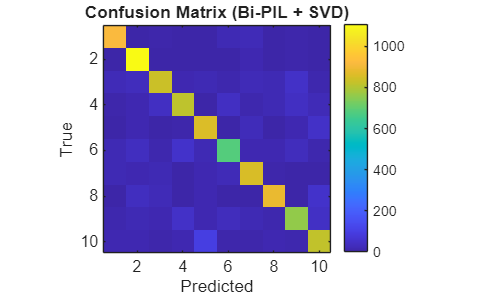


%% ================= CONFUSION MATRIX =================

conf_mat = zeros(10,10);
for i = 1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = ...
        conf_mat(y_test(i)+1,pred(i)+1) + 1;
end

figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
title('Confusion Matrix (Bi-PIL + SVD)');
axis square;